# **Script illustrating the relationship between cone spacing and point spread function in the default cone mosaic and optics models for the treeshrew and the human visual system**

*This script illustrates the relationship between cone spacing and the PSF in the treeshrew and in the human TreeShrew cone mosaics.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Generate default human and treeshrew optics (both with 3.0mm pupil) and human and treeshrew cone mosaics

% Generate default optics for the treeshrew and the human with a common
% pupil size
pupilDiameterMM = 3;
defaultTreeShewOI = oiTreeShrewCreate(...
    'name', 'treeshrew-GaussPSF', ...
    'pupilDiameterMM', pupilDiameterMM);
defaultHumanOI = oiCreate('wvf human', pupilDiameterMM);

% Generate a 1 deg tree shew cone mosaic with default params
defaultTreeShewConeMosaic = coneMosaicTreeShrewCreate(...
    defaultTreeShewOI.optics.micronsPerDegree, ...
    'fovDegs', [1 1]);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 68
Scones after making an S-cone free central patch: 68 (added Lcones:0, added Mcones:0)
Scones after pass 1: 39 (added Lcones:33, added Mcones:0)
Scones after pass 2: 23 (added Lcones:22, added Mcones:0)
Scones after pass 3: 13 (added Lcones:12, added Mcones:0)
Scones after pass 4: 11 (added Lcones:3, added Mcones:0)
Scones after pass 5: 11 (added Lcones:0, added Mcones:0)



% Generate a 0.2 deg human cone mosaic with default params
defaultHumanConeMosaic = coneMosaicHex(7, ...
    'fovDegs', [0.2 0.2]);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 103
Scones after making an S-cone free central patch: 0 (added Lcones:69, added Mcones:34)


# **Step 2.** Co-visualize PSFs and cone mosaics - 3mm pupil

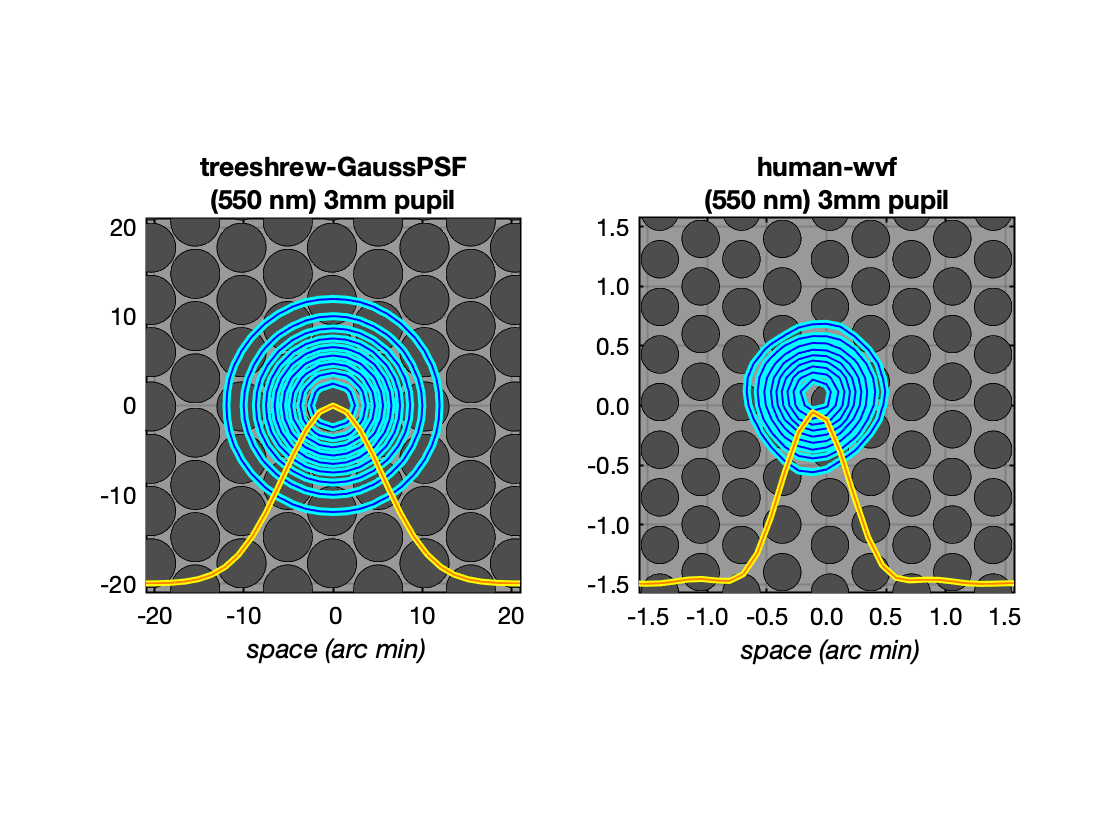

% Co-visualize the default treeshrew PSF and cone mosaic
visualizedWavelength = 550;
visualizedSpatialSupportArcMin = 40;
figure(); clf;
ax = subplot(1,2,1);
visualizePSF(defaultTreeShewOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultTreeShewConeMosaic, ...
    'axesHandle', ax);

% Co-visualize the default human PSF and cone mosaic
visualizedSpatialSupportArcMin = 3;
ax = subplot(1,2,2);
visualizePSF(defaultHumanOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'axesHandle', ax);

# **Step 3.** Generate optics with smaller pupil size (2.0 mm)

% Generate default optics for the treeshrew and the human with a common
% pupil size
pupilDiameterMM = 2;
defaultTreeShew2mmOI = oiTreeShrewCreate(...
    'pupilDiameterMM', pupilDiameterMM, ...
    'name', 'treeshrew-GaussPSF');
defaultHuman2mmOI = oiCreate('wvf human', pupilDiameterMM);

# **Step 4.** Co-visualize PSFs and cone mosaics - 2 mm pupil

Note that the human PSF (which is wavefront-aberration based) increases in spread when the pupil decreases, whereas the treeshrew PSF does not. We probably need to built that dependency into the treeshrew optics.

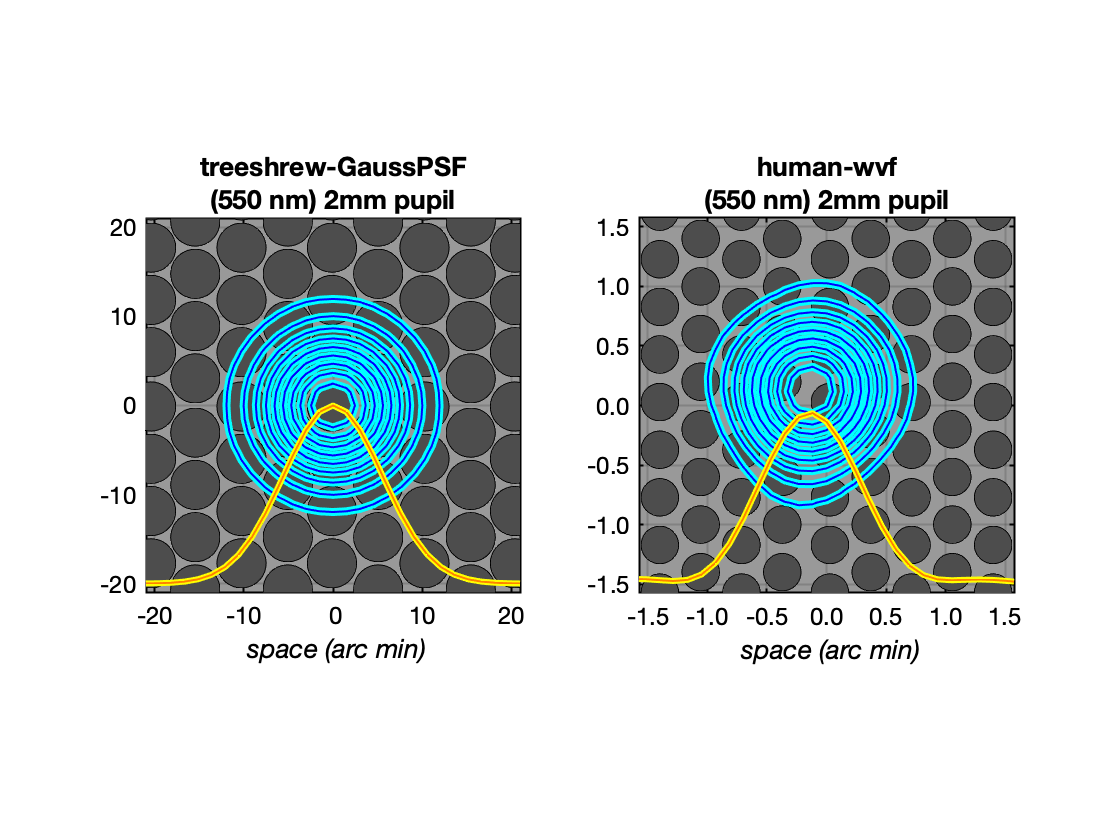

% Co-visualize the 2mm treeshrew PSF and cone mosaic
visualizedWavelength = 550;
visualizedSpatialSupportArcMin = 40;
figure(); clf;
ax = subplot(1,2,1);
visualizePSF(defaultTreeShew2mmOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultTreeShewConeMosaic, ...
    'axesHandle', ax);

% Co-visualize the 2 mm human PSF and cone mosaic
visualizedSpatialSupportArcMin = 3;
ax = subplot(1,2,2);
visualizePSF(defaultHuman2mmOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'axesHandle', ax);

# **Step 5.** Co-visualize PSFs and cone mosaics - 2 mm pupil, now at 500 nm

Here note that the human PSF (which is wavefront-aberration based) changes in shape as a function of wavelength (due to axial chromatic aberration), whereas the treeshrew PSF does not. 

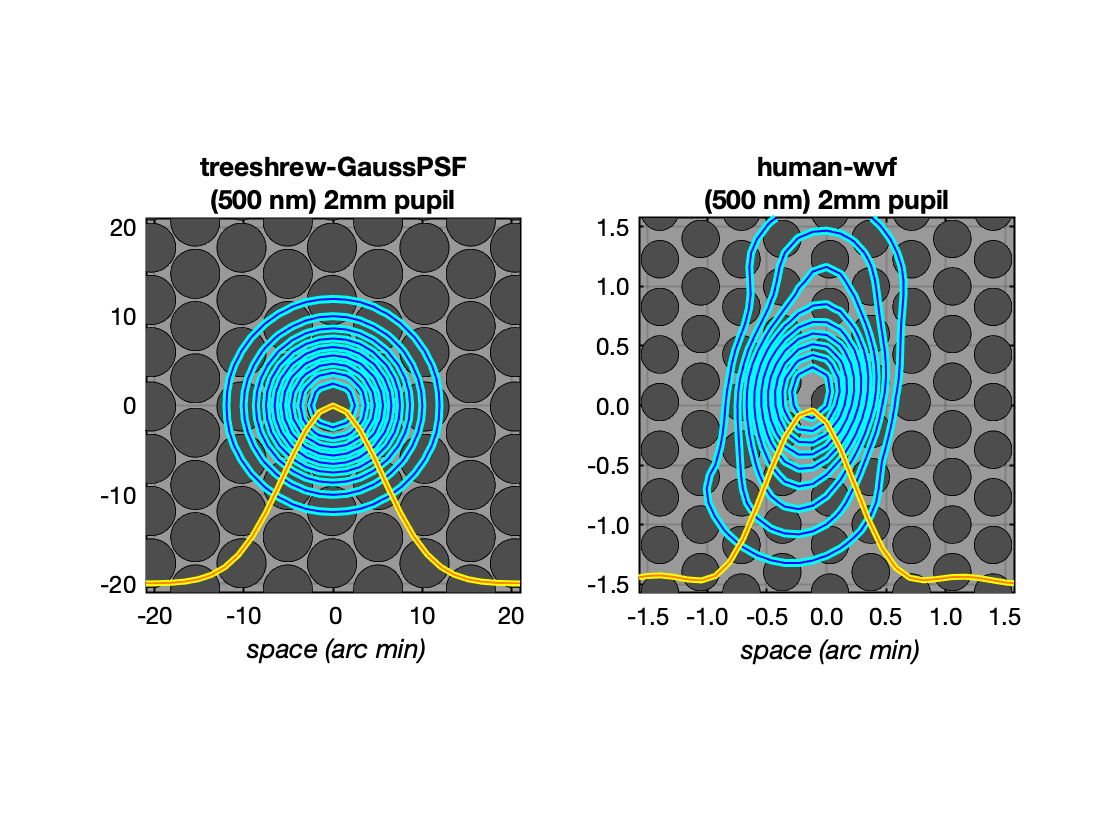

% Visualize the 2mm PSFs at 500 nm
visualizedWavelength = 500;
visualizedSpatialSupportArcMin = 40;
figure(); clf;
ax = subplot(1,2,1);
visualizePSF(defaultTreeShew2mmOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultTreeShewConeMosaic, ...
    'axesHandle', ax);

% Co-visualize the 2 mm human PSF and cone mosaic
visualizedSpatialSupportArcMin = 3;
ax = subplot(1,2,2);
visualizePSF(defaultHuman2mmOI, visualizedWavelength, ...
    visualizedSpatialSupportArcMin, ...
    'withSuperimposedMosaic', defaultHumanConeMosaic, ...
    'axesHandle', ax);